% Load data
fileloc = fullfile('C:\Users\Elder\Dropbox (MIT)\BEC1\Processed Data\2016\2016-02\2016-02-23','EoS_data_23feb.mat');
temp = load(fileloc,'EoS_data_23feb'); data = temp.EoS_data_23feb;
images = data(:,1);
heats = cell2mat(data(:,2));
heat_bins = unique(heats);
econst.pixelsize = 1.44e-6; econst.fudge = 1.837; uconst.sigma0 = 6*pi*((671*10^-9)/(2*pi))^2;
clearvars temp data;

%% Import an image

% data = imagedata(images{1},'crop',{'rect',271,218,135,350},'bg',{'avg',20},'plot',{1},'Nsat',630*5/10);
% z_i_raw = (1:size(data.od2,1))' * econst.pixelsize;
% [xsec_area, corrected_data] = get_xsection_area(data.od2,(120:5:215)',econst.pixelsize,1);
% n_z = sum(data.od2,2) ./ (xsec_area / econst.pixelsize * (uconst.sigma0 / 2)) * econst.fudge;
% figure; plot(z_i_raw * 10^6, n_z,'b.'); xlabel('z (um)'); ylabel('density n(z)');
% fitres = createFitTFnz(z_i_raw,n_z,1);
% z_i = z_i_raw - fitres.x0;
% figure; plot(z_i * 10^6, n_z,'b.'); xlabel('z (um)'); ylabel('density n(z)'); grid on;
% clearvars data z_i_raw corrected_data xsec_area fitres

%% Import all images

% % imdata = cell(size(images));
% % progress = waitbar(0);
% % for i = 1:length(imdata)
% %     data = imagedata(images{i},'crop',{'rect',271,218,135,350},'bg',{'avg',20},'plot',{0},'Nsat',630*5/10);
% %     z_i_raw = (1:size(data.od2,1))' * econst.pixelsize;
% %     [xsec_area, corrected_data] = get_xsection_area(data.od2,(120:2:215)',econst.pixelsize,0);
% %     n_z = sum(data.od2,2) ./ (xsec_area / econst.pixelsize * (uconst.sigma0 / 2)) * econst.fudge;
% %     fitres = createFitTFnz(z_i_raw,n_z,0);
% %     z_i = z_i_raw - fitres.x0;
% %     imdata{i} = setfield(imdata{i},'imagename',images{i});
% %     imdata{i} = setfield(imdata{i},'heattime',heats(i));
% %     imdata{i} = setfield(imdata{i},'data',data);
% %     imdata{i} = setfield(imdata{i},'z_i',z_i);
% %     imdata{i} = setfield(imdata{i},'n_z',n_z);
% %     imdata{i} = setfield(imdata{i},'data2',corrected_data);
% %     imdata{i} = setfield(imdata{i},'xsec_area',xsec_area);
% %     imdata{i} = setfield(imdata{i},'TFfitres',fitres);
% %     waitbar(i/length(imdata));
% % end
% % close(progress);
% % 
% % clearvars data z_i_raw corrected_data xsec_area fitres n_z z_i i
% % save('EoS_data_23feb.mat','imdata','-append');

%% Load all data from saved file

% % temp = load(fileloc); imdata = temp.imdata; clearvars temp;

%% Process single image
z_i = getfield(imdata{30},'z_i');
n_z = getfield(imdata{30},'n_z');
disp(getfield(imdata{30},'heattime'))

    12



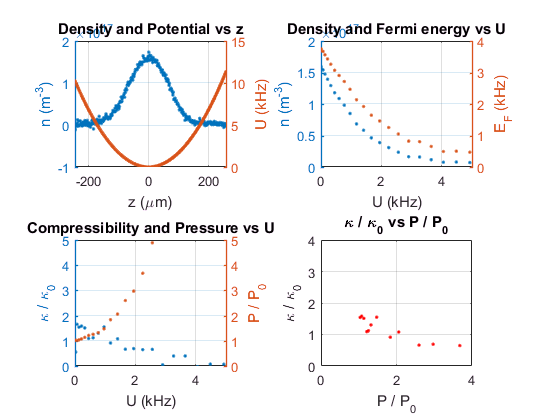

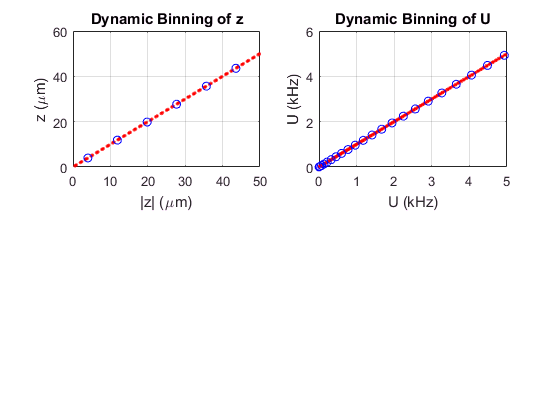


set.plotset = {1, 5};
set.techplotset = {1,50};
set.bins = 5;
set.Urange = [0.05 3];
% Regular diff and sum
set.methods = {'trapz','diff',1,2};
EoS1 = EoS_nz_KvsP_s( z_i, n_z, 'methods',set.methods,'plot',set.plotset,'techplot',set.techplotset,'bins',set.bins,'Urange',set.Urange);

%% Process all images

set.plotset = {0, 5};
set.techplotset = {0,50};
set.bins = 6;
set.Urange = [0.01 3];
set.methods = {'trapz','diff',1,2};
for i = 1:length(imdata)
    EoS = EoS_nz_KvsP_s( getfield(imdata{i},'z_i'), getfield(imdata{i},'n_z') / 1.837 * 2.8 , 'methods',set.methods,'plot',set.plotset,'techplot',set.techplotset,'bins',set.bins,'Urange',set.Urange);
    imdata{i} = setfield(imdata{i},'k_U',EoS.k_U(EoS.i1:EoS.i2));
    imdata{i} = setfield(imdata{i},'P_U',EoS.P_U(EoS.i1:EoS.i2));
end

%% Plotting
plot_heattime = 10;
all_k = [];
all_P = [];

figure; subplot(1,1,1); hold on;
for i = 1:length(imdata)
    if getfield(imdata{i},'heattime')==plot_heattime
        plot(getfield(imdata{i},'P_U'),getfield(imdata{i},'k_U'),'-');
        all_k = [all_k; getfield(imdata{i},'k_U')];
        all_P = [all_P; getfield(imdata{i},'P_U')];
    end
end
xlim([0 4]); ylim([0 4]); 
hold off;

% bin_P = ([0.3:0.02:6])';
% bin_k = zeros(size(bin_P)); std_k = bin_k;
% whichbin = discretize(all_P,bin_P-(bin_P(2)-bin_P(1))/2);
% for i = 1:length(bin_P)
%     binmem = all_k(whichbin==i); 
%     if isempty(binmem), binmem = 0; end
%     bin_k(i) = mean(binmem);
%     std_k(i) = std(binmem);
% end

[all_P, index ] = sort(all_P);
all_k = all_k(index);
all_k(all_P>5) = [];
all_P(all_P>5) = [];
binlen = 4;
bin_k = [];
bin_P = [];
ibin = 0;
for i = 1:binlen:length(all_P)-binlen
    ibin = ibin+1;
    bin_k(ibin) = mean(all_k(i:i+binlen));
    bin_P(ibin) = mean(all_P(i:i+binlen));
end


[ KappaTilde, PTilde, TTilde, Z_vec ] = VirialUnitarity(  2, 5, 1000 , 3 );
figure;
plot(bin_P, bin_k, 'r.','MarkerSize',10); hold on; plot( (0.1:0.01:4),1./(0.1:0.01:4));
plot(PTilde, KappaTilde,'g-');
xlim([0 5]); ylim([0 4]); 